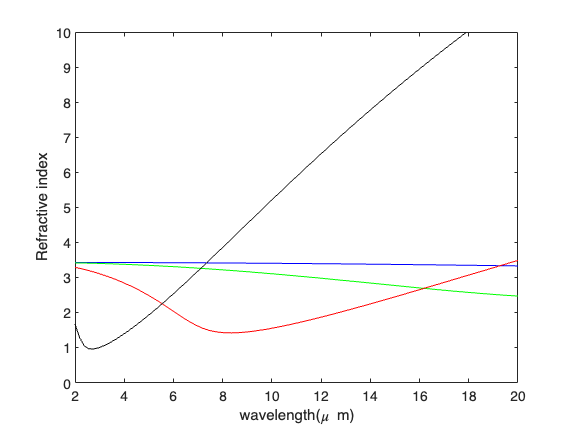

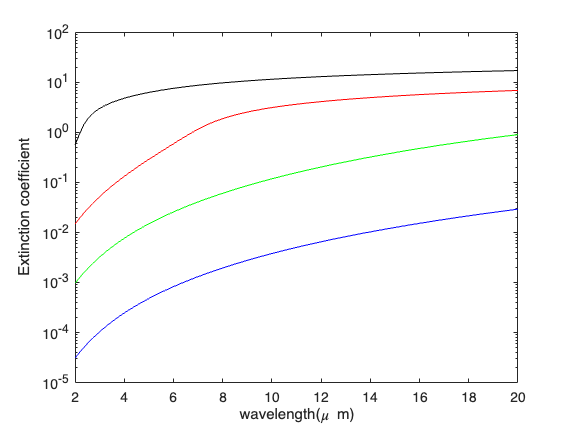

clc;
clear;
v=2.99792458*10^8;%light speed vacuum
wavelength=linspace(2,20,100)*10^-6;%ui miu*m
omega_all=2*pi*v./wavelength;
examples_doping_concentration=[10^18,10^19,10^20,10^21];% ui cm-3
T=293;
all=zeros(length(wavelength),2,length(examples_doping_concentration));
j=1;
for N=examples_doping_concentration

    for i=1:length(wavelength)
        omega=omega_all(i);
        [n,k]=doped_silicon(N,'p',T,omega);
        all(i,1,j)=n;
        all(i,2,j)=k;
    end
    j=j+1;
end
color={'blue','g','red','black'};
for k=1:length(examples_doping_concentration)
    figure(1)
    plot(wavelength/10^-6,all(:,1,k),"Color",color{k})
    xlabel('wavelength(\mu m)')
    ylabel('Refractive index')
    ylim([0 10])
    hold on 
    figure(2)
    semilogy(wavelength/10^-6,all(:,2,k),"Color",color{k}); 
    xlabel('wavelength(\mu m)')
    ylabel('Extinction coefficient')
    hold on 
end